### Einlesen der Testdaten

data = readtable("parameter_in_x_dd6.csv")

data = 10826×7 table
    Name    vtheta    vtheta_ref    vx    vx_ref    vy    vy_ref
    ____    ______    __________    __    ______    __    ______

      0       0           0         0       0       0       0   
     10       0           0         0       0       0       0   
     20       0           0         0       0       0       0   
     30       0           0         0       0       0       0   
     40       0           0         0       0       0       0   
     50       0           0         0       0       0       0   
     60       0           0         0       0       0       0   
     70       0           0         0       0       0       0   
     80       0           0         0       0       0       0   
     90       0          


%x2 = import

% geforcte Zielwerte (ref)
x2_r = table2array([ data(:,"vx_ref") data(:,"vy_ref")  data(:,"vtheta_ref")
])

x2_r =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



% measuremented values
x2 = table2array([ data(:,"vx") data(:,"vy")  data(:,"vtheta")
])

x2 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



% Set length for vectors to prevent size problems after operations (e.g.
% diff() or NaN at end of file)
vecLen = size(x2_r)-10

vecLen =        10816          -7


### Filter to get rid of impulses

windowSize = 50; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

%%filter to get rid of impulses caused by diff()
x2_t = filter(b,a,diff(x2))

x2_t =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x2_rt = filter(b,a, diff(x2_r))

x2_rt =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



% make vector same length (diff shortens vector length by 1)
x2 = x2(1:vecLen,:)

x2 =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x2_r= x2_r(1:vecLen,:)

x2_r =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x2_t= x2_t(1:vecLen,:)

x2_t =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


x2_rt= x2_rt(1:vecLen,:)

x2_rt =      0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


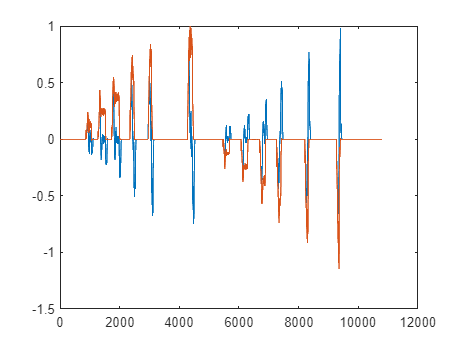


figure
plot(x2_t/abs(max(x2_t)))   %plot derived measurements dx2/dt normalized
hold on
plot(x2(:,1)/ abs(max(x2(:,1)))) %plot measurements dx2 normalized

### Parameterschaetzung

%x2_t = pi1*x2 - pi2*sgn(x2) + u = PI*[x2; sgn(x2)] + u

regressor = [-x2(1:vecLen,:) -sign(x2(1:vecLen,:))];
regressor = regressor(1:vecLen,:)

regressor =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


pi = regressor\(x2_t-x2_rt)

pi =    -0.0097   -0.0000   -0.0000
   -0.0048   -0.0089    0.0000
    0.1031   -0.6809   -0.0166
    2.0042    0.0016    0.0000
    0.0417    0.0048   -0.0001
   -0.1905    0.0316    0.0002


pi1 = pi(1:3,:)

pi1 =    -0.0097   -0.0000   -0.0000
   -0.0048   -0.0089    0.0000
    0.1031   -0.6809   -0.0166


pi2 = pi(4:6,:)

pi2 =     2.0042    0.0016    0.0000
    0.0417    0.0048   -0.0001
   -0.1905    0.0316    0.0002



x2_ts = -pi1*x2(1:vecLen,:)'-pi2*sign(x2(1:vecLen,:))'+x2_rt'

x2_ts =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



hold off

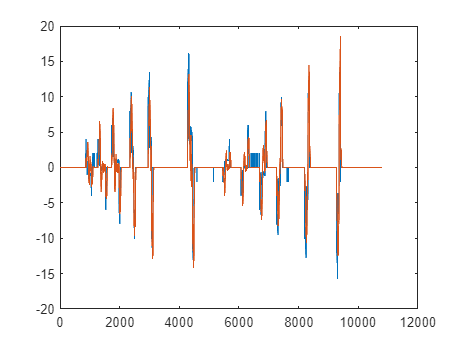

figure
plot(x2_ts(1,:))
hold on;
plot(x2_t(:,1))